## Load the Data and place into seperate containers

clear;
load exp1.mat 
time = exp1.X.Data;
vel_motor = exp1.Y(1).Data;
vel_table = exp1.Y(2).Data;
voltage = exp1.Y(3).Data;

## Plot for visualization

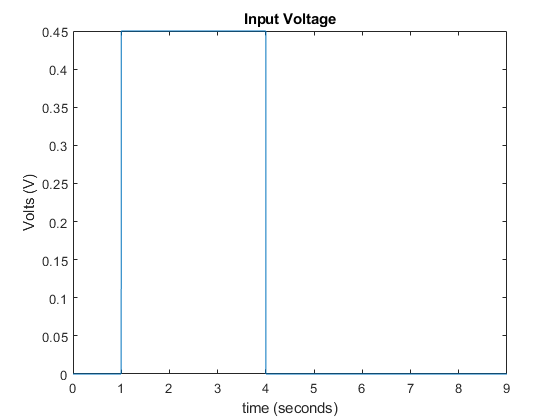

plot(time,voltage)
title('Input Voltage')
ylabel('Volts (V)')
xlabel('time (seconds)')

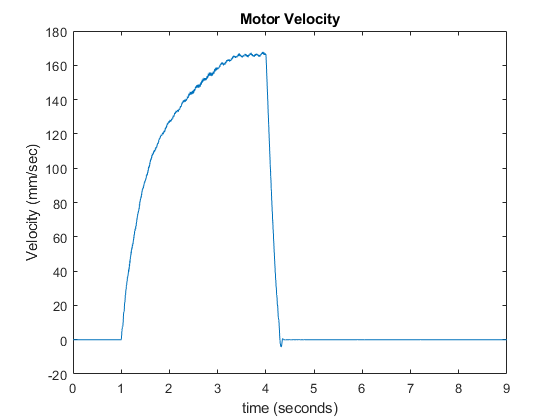


plot(time,vel_motor)
title('Motor Velocity')
ylabel('Velocity (mm/sec)')
xlabel('time (seconds)')

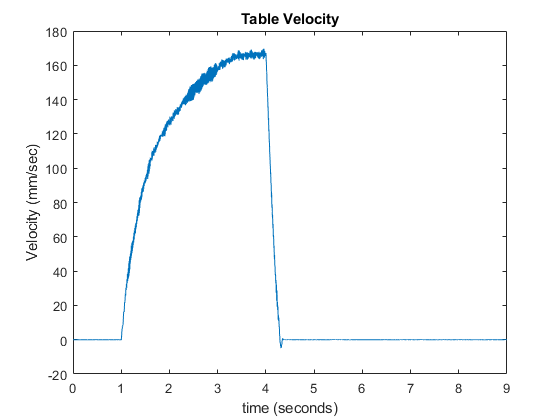


plot(time,vel_table)
title('Table Velocity')
ylabel('Velocity (mm/sec)')
xlabel('time (seconds)')

## Find the max table Velocity and Time Constant $\tau_m$

[max_table_vel, max_idx] = max(vel_table);
step_voltage_value = max(voltage);

%We know $\tau_m$ is is the time where the velocity reaches 63% of the final value
% The 1:4000 is to prevent finding a time on the slowdown edge
[minValue, closestIndex] = min(abs(vel_table(1:4000)-0.63*max_table_vel));
tau_m = time(closestIndex)-1; % -1 is for the 1 second delay


## Fine $B_e$ and $J_e$

% From the final value theorem we know V_input/Be = max_table_vel
Be = step_voltage_value/max_table_vel;
%tau_m = Je/Be
Je = (tau_m * Be);

## Build and Compare transfer function with found parameters

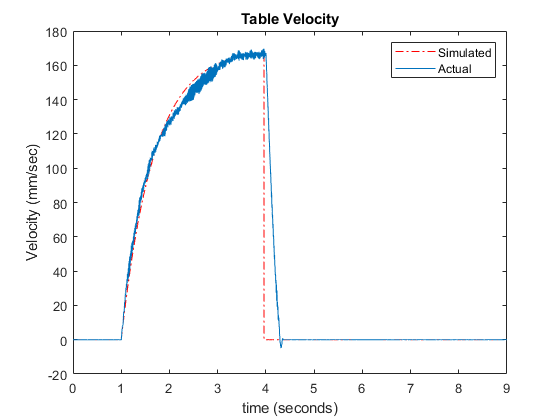

num = [1];
den = [Je Be];
G = tf(num,den);
t_step = 0:0.001:(max_idx-1000)/1000;
opt = stepDataOptions('StepAmplitude',step_voltage_value);
y = step(G,t_step,opt);
x = zeros(1,numel(time));
x(1001:1000+numel(y)) = y';

plot(time,x,'r-.')
hold on 
plot(time,vel_table)
title('Table Velocity')
ylabel('Velocity (mm/sec)')
xlabel('time (seconds)')
legend('Simulated', 'Actual')